# Accessing Behavioral Data from the Allen Brain Observatory

This tutorial demonstrates access of the behavioral data from the Visual Coding Neuropixels and Visual Coding 2P datasets from the Allen Brain Observatory. Behavioral data includes running speed, pupil information, and stimulus presentations, along with several other measurements [1]. This tutorial places a particular emphasis on the stimuli data from the Neuropixels and 2P datasets.

### Electrophysiology Data

The first part of this tutorial examines behavioral data from the ephys recordings in the Visual Coding Neuropixels dataset.

#### Accessing Behavioral Data

Behavioral data such as pupil and stimuli information are part of an ephys `session` object's *Linked File Values* properties and are accessed via `.<LinkedFileValues> `once the `session` object has been obtained. Below, we first obtain a session from the Neuropixels dataset.

% obtain a session from the ephys dataset
availEphysSessions = bot.fetchSessions('ephys');
desiredEphysSessions = availEphysSessions(availEphysSessions.session_type == 'brain_observatory_1.1', :);
desiredEphysSessions = desiredEphysSessions(~desiredEphysSessions.fail_eye_tracking, :);
desiredEphysSessions = desiredEphysSessions(desiredEphysSessions.full_genotype == "wt/wt", :)

desiredEphysSessions = 13×15 table
       id        unit_count    channel_count    probe_count        session_type         age_in_days    fail_eye_tracking    sex    full_genotype                                                      ephys_structure_acronyms                                                      isi_experiment_id    date_of_acquisition     specimen_id      specimen      well_known_files
    _________    __________    _____________    ___________    _____________________    ___________    _________________    ___    _____________    ________________________________

ephysSessionUnderStudy = bot.session(desiredEphysSessions(1, :));

The *Linked File Values* properties and other properties of each session can now be examined.

disp(ephysSessionUnderStudy)

  EphysSession with properties:

                              info: [1×1 struct]
                                id: 742951821
                       linkedFiles: [2×1 table]

   Info Derived Values
                structure_acronyms: ["VIS"    "VISal"    "VISl"    "VISp"    "VISpm"    "VISrl"    "grey"]

   Linked Items
                            probes: [6×23 table]
                          channels: [2219×29 table]
                             units: [893×51 table]

   Linked Item Derived Values
       channel_structure_intervals: [18×2 table]
         structurewise_unit_counts: [7×2 table]

   Linked File Values ('SessNWB')
      inter_presentation_intervals: '[on demand]'
                     invalid_times: '[on demand]'
                    mean_waveforms: '[on demand]'
    optogenetic_stimulation_epochs: '[on demand]'
                        pupil_data: '[on demand]'
               pupil_dat

#### Visualizing Pupil Location

We will first examine the pupil data linked to an ephys session. For a session, `.pupil_data`  can be used to retrieve pupil tracking data to visualize the pupil location as a location density map. Note that if the pupil data is unavailable, then a different session where the mouse did not fail eye tracking needs to be selected.

% get the table of pupil locations
pupil_loc = ephysSessionUnderStudy.pupil_data

pupil_loc = 288131×16 table
    timestamps    corneal_reflection_center_x    corneal_reflection_center_y    corneal_reflection_height    corneal_reflection_width    corneal_reflection_phi    pupil_center_x    pupil_center_y    pupil_height    pupil_width    pupil_phi    eye_center_x    eye_center_y    eye_height    eye_width    eye_phi 
    __________    ___________________________    ___________________________    _________________________    ________________________    ______________________    ______________    ______________    ____________    ___________</

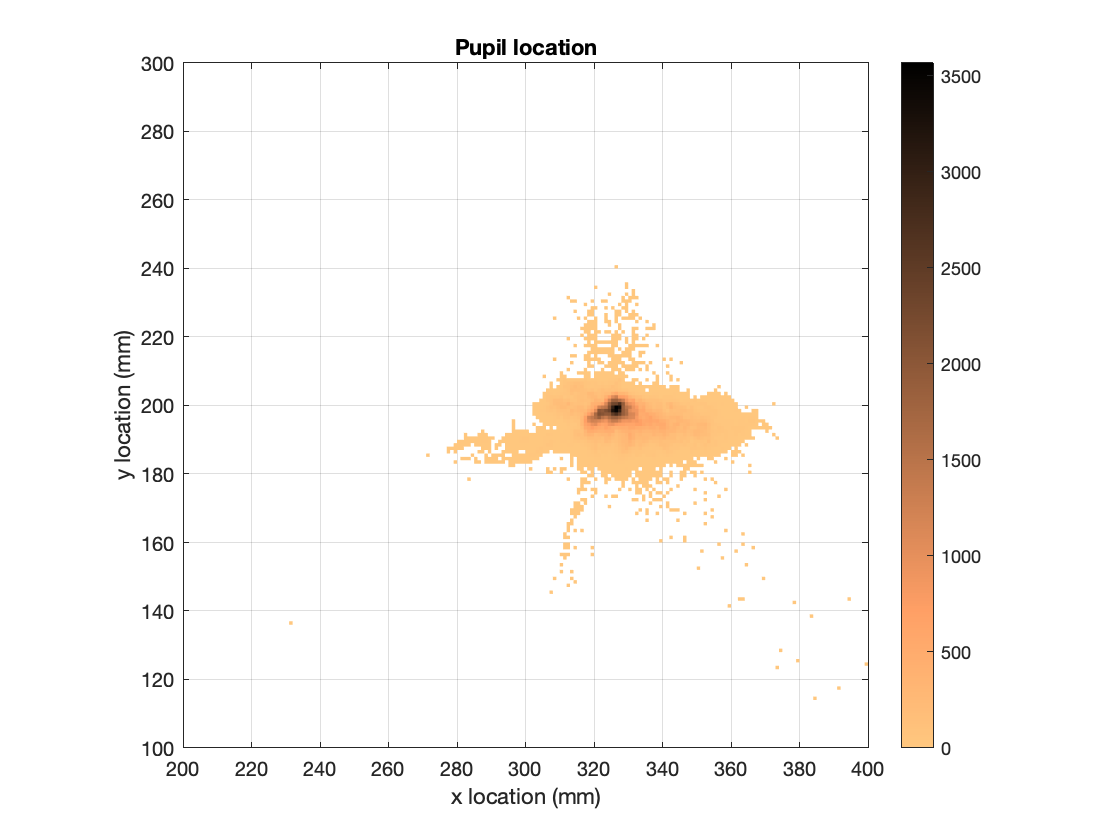

% plot a 2D histogram of pupil location
histogram2(pupil_loc.pupil_center_x, pupil_loc.pupil_center_y, 'DisplayStyle', 'tile');
xlim([200 400]);
ylim([100 300]);
cmap = copper();
colormap(cmap(end:-1:1, :));
axis square;
xlabel('x location (mm)');
ylabel('y location (mm)');
title('Pupil location');
colorbar

#### Accessing Stimulus Information

An ephys session's *Linked File Values* also contain stimulus-related properties, such as `.stimulus_names`, `.stimulus_conditions`, and `.stimulus_presentations`. These properties can be used to access stimulus information, such as details about the types of stimuli presented in the session, the stimulus parameters, and the order of the stimulus presentations.

Furthermore, in the Neuropixels dataset, two different stimulus sets were shown across the experiments, and this is reflected in the two different values under the `session_type `property: "`brain_observatory_1.1`" and "`functional_connectivity`." More information about the stimulus sets can be found [here](https://allensdk.readthedocs.io/en/latest/_static/neuropixels_stimulus_sets.png).

We first examine the types of stimuli presented in the session:

% show which stimuli were presented in this ephys session
ephysSessionUnderStudy.stimulus_names

ans = 8×1 string array
    "drifting_gratings"
    "flashes"
    "gabors"
    "natural_movie_one"
    "natural_movie_three"
    "natural_scenes"
    "spontaneous"
    "static_gratings"


Now, we examine the table of individual stimulus presentations:

% get a full table of individual stimulus presentations
stimuli = ephysSessionUnderStudy.stimulus_presentations;
head(stimuli)

ans = 8×18 table
    stimulus_presentation_id    stimulus_condition_id    stimulus_block_id    stimulus_block_condition_id    stimulus_name    start_time    stop_time    contrast    orientation                 phase                       size         spatial_frequency    stimulus_block    temporal_frequency    frame    x_position    y_position    color
    ________________________    _____________________    _________________    ___________________________    _____________    __________    _________    ________    ___________    

Note that since not all parameters are relevant to all stimuli, this table contains many NaN values [2].

Furthermore, this table contains several different types of IDs: 

- `stimulus_presentation_id - `the presentation ID is a counter for the stimulus presentations; each stimulus presentation has a different ID.

- `stimulus_condition_id - `the condition ID is a counter for unique sets of stimulus parameters (i.e., identical stimuli); stimulus presentations with identical parameters (except for time values and presentation IDs) have the same ID. Note that otherwise identical stimuli with different `stimulus_block_id` values will have different `stimulus_condition_id` values. 

- `stimulus_block_id - `the block ID is a counter that increases for each presented block (or epoch) of a stimulus type and equals the index of the block containing the stimulus presentation; stimulus presentations within the same block have the same ID. Note that a stimulus block, or epoch, consists of a sequential group of presentations of the same stimulus type.

- `stimulus_block_condition_id - `the block condition ID is a counter for unique sets of stimulus parameters (i.e., identical stimuli) within a block; stimulus presentations within a block with identical parameters have the same ID [2].

For example, all the stimuli with a `stimulus_condition_id` of 1 are identical with respect to their set of stimulus parameters and have different `stimulus_presentation_ids.` 

stimuli(stimuli.stimulus_condition_id==1,:)

ans = 15×18 table
    stimulus_presentation_id    stimulus_condition_id    stimulus_block_id    stimulus_block_condition_id    stimulus_name    start_time    stop_time    contrast    orientation                 phase                       size         spatial_frequency    stimulus_block    temporal_frequency    frame    x_position    y_position    color
    ________________________    _____________________    _________________    ___________________________    _____________    __________    _________    ________    ___________    

The session property `.stimulus_epochs` can also be used to visualize the blocks of stimulus presentations.

head(ephysSessionUnderStudy.stimulus_epochs)

ans = 8×5 table
    start_time    stop_time    duration        stimulus_name        stimulus_block
    __________    _________    ________    _____________________    ______________

      24.686       84.753       60.067     "spontaneous"                 NaN      
      84.753       996.75       911.99     "gabors"                        0      
      996.75       1285.7       288.99     "spontaneous"                 NaN      
      1285.7       1584.3       298.52     "flashes"                       1      
      1584.3         1586       1.7514     "spontaneous"                 NaN      
        1586       2185.5        599.5     "drifting_gratings"             2      
      2185.5       2216.5       31.026     "spontaneous"                 NaN      
      2216.5         2817        600.5     "natural_movie_three"  

We can also examine the table of stimulus conditions:

% get a table with detailed parameters for each stimulus
head(ephysSessionUnderStudy.stimulus_conditions)

ans = 8×17 table
    stimulus_condition_id    stimulus_block_condition_id    stimulus_name    contrast      mask       opacity    orientation                 phase                       size         spatial_frequency    temporal_frequency      units      frame    x_position    y_position      color_triplet      color
    _____________________    ___________________________    _____________    ________    _________    _______    ___________    ________________________________    ______________    _________________    ___________

In this table, each row, containing a different `stimulus_condition_id`, is distinct and contains a unique set of stimulus parameters, as mentioned above [2].

From these tables, information about the the stimulus name, presentation start time, presentation stop time, orientation, x position, and y position can be obtained for the stimulus presentations.

#### Obtaining Spike Statistics

The methods `getConditionwiseSpikeStatistics(),` `getPresentationwiseSpikeCounts(), `and `getPresentationwiseSpikeTimes` compute spike statistics for the stimuli in an ephys session.

- `getConditionwiseSpikeStatistics() `computes spike statistics on data grouped by stimulus conditions

- `getPresentationwiseSpikeCounts()`  returns spike counts for different stimulus presentations

- `getPresentationwiseSpikeTimes()` returns a table of spike times for different stimulus presentations

All of these methods take as arguments the presentation IDs of the desired stimuli and the IDs of the desired units from which spike statistics will be computed.

### Optical Physiology Data

The second part of this tutorial examines behavioral data from the ophys recordings in the Visual Coding 2P dataset.

#### Accessing Behavioral Data

The procedure is the same as with the Neuropixels data:

% obtain a session from the ophys dataset
availOphysSessions = bot.fetchSessions('ophys');
desiredOphysSessions = availOphysSessions(ismember(availOphysSessions.targeted_structure_acronym, categorical(["VISal" "VISrl" "VISam"])), :);
desiredOphysSessions = desiredOphysSessions(desiredOphysSessions.cre_line == "Cux2-CreERT2", :);
desiredOphysSessions = desiredOphysSessions(desiredOphysSessions.imaging_depth == 175,:);
desiredOphysSessions = desiredOphysSessions(~desiredOphysSessions.fail_eye_tracking, :);
desiredOphysSessions = desiredOphysSessions(desiredOphysSessions.stimulus_name == "three_session_A", :);
ophysSessionUnderStudy = bot.session(desiredOphysSessions(1,:));

to cache location: /external/neuralcoding/prod6/specimen_495727000/ophys_experiment_503412730/503412730.nwb...
Download complete.


disp(ophysSessionUnderStudy)

  OphysSession with properties:

                                   info: [1×1 struct]
                                     id: 503412730
                           session_type: three_session_A
                            linkedFiles: [2×1 table]

   Linked File Values ('SessNWB')
                      cell_specimen_ids: '[on demand]'
          corrected_fluorescence_traces: '[on demand]'
                fluorescence_timestamps: '[on demand]'
                    fluorescence_traces: '[on demand]'
            fluorescence_traces_demixed: '[on demand]'
                fluorescence_traces_dff: '[on demand]'
                         max_projection: '[on demand]'
                      motion_correction: '[on demand]'
                             neuropil_r: '[on demand]'
                        neuropil_traces: '[on demand]'
                           nwb_metadata: '[on demand]'
                         

#### Obtaining Pupil Data

For an ophys session, `.pupil_location `and `.pupil_size` can be used instead to obtain timetables containing pupil information.

head(ophysSessionUnderStudy.pupil_size)

ans = 8×1 timetable
    timestamps    pupil_areas
    __________    ___________

    9.9738 sec        3484   
    10.007 sec      3473.7   
    10.04 sec       3302.8   
    10.073 sec      3407.1   
    10.106 sec      3358.8   
    10.14 sec       3307.3   
    10.173 sec      3528.2   
    10.206 sec      3304.4   


#### Accessing Stimulus Information

An ophys session's *Linked File Values* contain stimulus-related properties as well, such as `.stimulus_list`.

% show which stimuli were presented in this ophys session
ophysSessionUnderStudy.stimulus_list

ans = 1×4 cell array
    {'drifting_gratings'}    {'natural_movie_one'}    {'natural_movie_three'}    {'spontaneous'}


The methods `getStimulusTable()` and `getStimulusTemplate()` can then be used to obtain detailed frame-by-frame information about the stimuli that were presented.

% obtain details for stimulus drifting gratings
head(getStimulusTable(ophysSessionUnderStudy,'drifting_gratings'))

ans = 8×5 table
    temporal_frequency    orientation    blank_sweep    start_frame    end_frame
    __________________    ___________    ___________    ___________    _________

             1                270             0             735           795   
             4                135             0             825           885   
            15                 90             0             916           976   
             2                225             0            1006          1066   
             1                180             0            1097          1157   
             4                315             0            1187          1247   
             2                225             0            1278          1338   
             1                 90             0            1368          1428   


### Conclusion

This tutorial illustrates access of the behavioral data from both the Neuropixels and 2P datasets, and an emphasis is placed on explaining stimulus details and properties.

### References

[1] [https://allensdk.readthedocs.io/en/latest/visual_behavior_optical_physiology.html](https://allensdk.readthedocs.io/en/latest/visual_behavior_optical_physiology.html).

[2] Copyright 2019 Allen Institute for Brain Science. Visual Coding Neuropixels. Available from: [https://allensdk.readthedocs.io/en/latest/_static/examples/nb/ecephys_session.html](https://allensdk.readthedocs.io/en/latest/_static/examples/nb/ecephys_session.html).